- **0 ile 100 arasında rastgele sayılardan oluşan 20x20 M isimli bir matris tanımlayınız. Bu matrisi ekrana yazdırınız. Bu matrisin boyutunu 100x100 olacak şekilde genişletip 20x20 olan kısmına müdahele etmeden genişleyen yerlerdeki tüm değerleri bir tamsayı değişkeninde saklanabilecek maksimum sayı ile değiştiriniz. **

M = randi(100, 20,20)

M =     48    64    87    37    59    89    59    93    25     4    86    87    35     6    25     9    40    73    21    30
    16    95    27    77    27    40    16    70    67    62    88    94    45    53     6    78     7    12     9    61
    35    21    32    63     5    77    20    59     9    37    28    99     6    34    45    91    79    12    78    97
    61    71    12    78    76    40    41    82    63     5    21    86    18    18     2    54    34    65    21    44
    20    24    94    94    25    81    75    88    67    49    57    79    67    21    90    11    61    33    39    70
    74    12    65    98    45    76    83    99    73    20    65    52    34    91    20    83    75    66    56    76
    25    61    48    20    69    38    79     1    90    13    42    18    90    68    10    34    11    75    23    44
    92    46    64    14    36    22    32    87    99    21    21    40    12    47    31    30    13    59    65    66
    27    46    55    70    

a = intmax;
M(21:100, 21:100) = intmax;
M(1:20, 21:100) = intmax;
M(21:100, 1:20) = intmax;
M

M = 	1.0e+09 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475   

M(1,1)

ans = 48

**2. M matrisinin 20x20 parçasını sağ alt köşeye (20x20) kopyalayın. Sağ üst köşeye(20x20) sayıların iki katını, sol alt köşeye (20x20) 5 katını atayarak yerleştirin. **

M(81:100, 81:100) = M(1:20,1:20);
M(1:20, 81:100) = M(1:20,1:20)*2;
M(81:100, 1:20) = M(1:20,1:20)*5;
M

M = 	1.0e+09 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475    2.1475   

**3. Bu matrisin köşegen elemanlarının toplamını bulunuz.**

sumdiagonal = trace(M)

sumdiagonal = 1.2885e+11

**4. Bu matrisin her bir satırının ortalaması ve en küçük değerleri, her bir sütun için de en büyük değerleri bulup ekrana yazdırın. **

row_mean = mean(M, 2)

row_mean = 	1.0e+09 *

    1.2885
    1.2885
    1.2885
    1.2885
    1.2885
    1.2885
    1.2885
    1.2885
    1.2885
    1.2885


row_min = min(M, [], 2)

row_min = 	1.0e+09 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


**5. Rastgele değerlerden oluşan 5x4 ve 4x8 iki matris üretin. Bu matrislerin çarpımı ile matrislerin elemanlarının karşılıklı çarpımlarını ayrı ayrı yazdırın. **

matris1 = rand(5,4);
matris2 = rand(4,8);
matriscarpimi = matris1*matris2

matriscarpimi =     0.5469    1.0952    0.5181    1.3390    1.0343    0.8563    1.4285    0.8824
    0.3754    0.8385    0.5108    1.0512    0.8486    0.3420    0.7108    0.3435
    0.3075    0.7856    0.2207    0.5916    0.8280    0.2123    0.5259    0.2771
    0.2711    0.6356    0.3128    0.6811    0.6516    0.2248    0.4927    0.2443
    0.2110    0.3671    0.4649    0.8169    0.2650    0.3075    0.4505    0.2475


karsilikliCarpim = dot(matris1(1:4,1:4),matris2(1:4,1:4))

karsilikliCarpim =     0.3145    0.3641    0.5504    0.7725


**6. 10 boyutunda rastgele vektör oluşturun ve maksimum değeri 0 ile değiştirin.**

A = randi(100,1,10)

A =     88    36    69    30    54    84    60    34    30    46


A(find(A == max(A))) = 0

A =      0    36    69    30    54    84    60    34    30    46


**7. 100x150 boyutlu bir matrisinin her bir satırındaki değerleri satır numarası olacak şekilde MM değişkeninde tanımlayınız.**

B = ones(100,150)

B =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1   

dimensions = size(B);
for i = 1: dimensions(1)
    for j = 1: dimensions(2)
        B(i,j) = B(i,j)*i;
    end
end
B

B =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3
     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4   

**8. MM matrisinin dört parçaya bölündüğünü düşünün. Sağ alt köşe (25x25) ile sol üst köşeyi(25x25), sağ üst köşe(25x25) ile sol alt köşedeki(25x25) değerlerin yerini değiştirin.**

B(1:25, 1:25) = B(76:100, 126:150);
B(76:100, 1:25) = B(1:25, 126:150);
B

B =     76    76    76    76    76    76    76    76    76    76    76    76    76    76    76    76    76    76    76    76    76    76    76    76    76     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
    78    78    78    78    78    78    78    78    78    78    78    78    78    78    78    78    78    78    78    78    78    78    78    78    78     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3
    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79   

**9.  10x10 bir matris içinde 1'den 100'e kadar rakamları saklayın. Bu matrisinin transpozunu yine aynı değişken içerisinde saklayın. Örtüşme olmadığından emin olun.**

C = 1:100;
C = reshape(C, [10,10])

C =      1    11    21    31    41    51    61    71    81    91
     2    12    22    32    42    52    62    72    82    92
     3    13    23    33    43    53    63    73    83    93
     4    14    24    34    44    54    64    74    84    94
     5    15    25    35    45    55    65    75    85    95
     6    16    26    36    46    56    66    76    86    96
     7    17    27    37    47    57    67    77    87    97
     8    18    28    38    48    58    68    78    88    98
     9    19    29    39    49    59    69    79    89    99
    10    20    30    40    50    60    70    80    90   100


C(11:20, 11:20) = C'

C =      1    11    21    31    41    51    61    71    81    91     0     0     0     0     0     0     0     0     0     0
     2    12    22    32    42    52    62    72    82    92     0     0     0     0     0     0     0     0     0     0
     3    13    23    33    43    53    63    73    83    93     0     0     0     0     0     0     0     0     0     0
     4    14    24    34    44    54    64    74    84    94     0     0     0     0     0     0     0     0     0     0
     5    15    25    35    45    55    65    75    85    95     0     0     0     0     0     0     0     0     0     0
     6    16    26    36    46    56    66    76    86    96     0     0     0     0     0     0     0     0     0     0
     7    17    27    37    47    57    67    77    87    97     0     0     0     0     0     0     0     0     0     0
     8    18    28    38    48    58    68    78    88    98     0     0     0     0     0     0     0     0     0     0
     9    19    29    39    

**10. opencv kütüphanesini kullanarak size verilen **[**yeni_dunya.pgm dosyasını**](https://edestek2.kocaeli.edu.tr/pluginfile.php/15245/mod_assign/intro/yeni_dunya.pgm)** okuyup eigen3 matris formatına dönüştürün. Bundan sonraki işlemler bu img_eigen matrisi üzerinden yapılacaktır. MATLAB ortamında yeni_dunya.pgm dosyasın okumak için kullanılacak fonksiyon : img = imread('yeni_dunya.pgm'); ekranda göstermek için fonksiyon: imshow(img)**

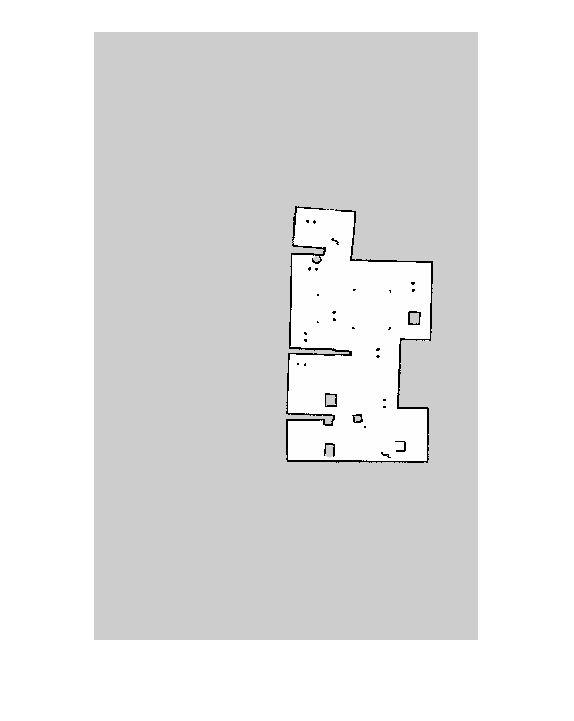

img = imread('yeni_dunya.pgm');
imshow(img)